## Thevenin/Norton equivalents

To find a Thevenin-equivalent, one usually follows the same procedure.

- Open-circuit the load element.

- Find voltage across the open gap.

- Short-circuit voltage sources and open-circuit current sources.

- Simplify to single impedance.

To illustrate this process, we load a circuit and decide to find the Thevenin-equivalent if we view $R_2$ as the load impendance.

circuit = Circuit('circuits/th_no_equivalents.txt');
circuit.list

ans =     'V1 1 0 DC 28
     V2 3 0 DC 7
     R1 1 2 4
     R2 2 0 2
     R3 2 3 1
     '


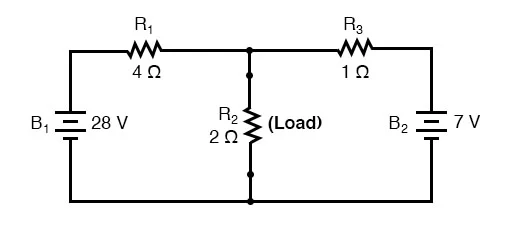

ELAB.evaluate(circuit)

Symbolic analysis successful (0.402158 sec).

Numerical evaluation successful (0.0509854 sec).


We open-circuit the load.

circuit.open(circuit.Resistors(2))
circuit.list

ans =     'V1 1 0 DC 28
     V2 3 0 DC 7
     R1 1 2 4
     R3 2 3 1
     '


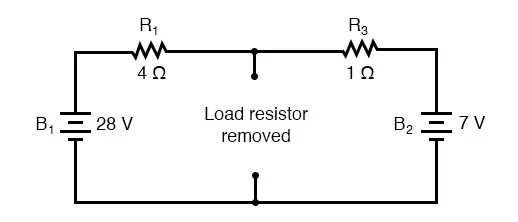

Then find the voltage across the gap, which is the Thevenin-equivalent voltage source.

ELAB.evaluate(circuit)

Symbolic analysis successful (0.251498 sec).

Numerical evaluation successful (0.0384221 sec).


circuit.numerical_node_voltages(2)

$$ans = v_{2}=\frac{56}{5}$$

We short all the voltage sources and simplify to find the Thevenin-equivalent impedance.

ELAB.remove_sources(circuit);
ELAB.simplify(circuit);
circuit.Resistors(1).impedance

$$ans = \frac{4}{5}$$

Of course, this process has also been condensed and given a high-level function.

circuit = Circuit('circuits/th_no_equivalents.txt');
ELAB.thevenin(circuit, circuit.Resistors(2));

Symbolic analysis successful (0.237976 sec).

Numerical evaluation successful (0.0397994 sec).


circuit.list

ans =     'Vth 1 0 DC 56/5
     Zth 1 2 4/5
     R2 2 0 2
     '


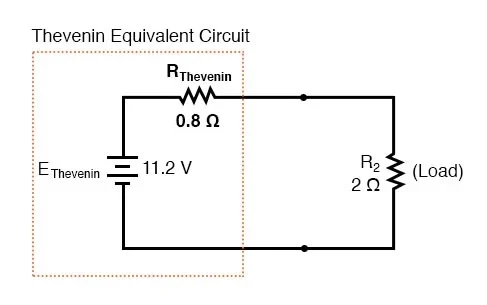

And there is a corresponding Norton-equivalent function, as well.

circuit = Circuit('circuits/th_no_equivalents.txt');
ELAB.norton(circuit, circuit.Resistors(2));

Symbolic analysis successful (0.245657 sec).

Numerical evaluation successful (0.0372693 sec).


circuit.list

ans =     'Ino 1 0 DC 14
     Zno 1 0 4/5
     R2 1 0 2
     '


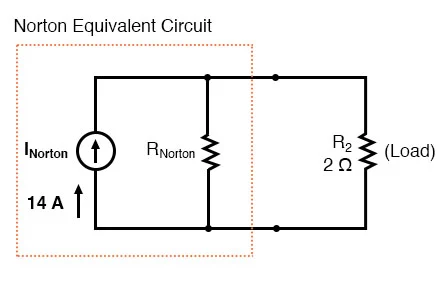

Both functions also handle purely symbolic or mixed circuits.

circuit = Circuit('circuits/th_no_equivalents_sym.txt');
circuit.list

ans =     'V1 1 0 DC V1
     V2 3 0 DC V2
     R1 1 2 R1
     R2 2 0 R2
     R3 2 3 R3
     '


ELAB.evaluate(circuit)

Symbolic analysis successful (0.306897 sec).

Numerical evaluation successful (0.114805 sec).


ELAB.thevenin(circuit, circuit.Resistors(2));

Symbolic analysis successful (0.242 sec).

Numerical evaluation successful (0.0688649 sec).


circuit.list

ans =     'Vth 1 0 DC (R1*V2+R3*V1)/(R1+R3)
     Zth 1 2 (R1*R3)/(R1+R3)
     R2 2 0 R2
     '


circuit = Circuit('circuits/th_no_equivalents_sym.txt');
ELAB.norton(circuit, circuit.Resistors(2));

Symbolic analysis successful (0.312427 sec).

Numerical evaluation successful (0.0701593 sec).


circuit.list

ans =     'Ino 1 0 DC (R1*V2+R3*V1)/(R1*R3)
     Zno 1 0 (R1*R3)/(R1+R3)
     R2 1 0 R2
     '
